
8793

ans = 8793

IAE = 6757.9002				P = 73.7145		I = 8.6765		D = 4.6366
IAE = 8807.1103				P = 33.4633		I = 11.1003		D = 6.9445
IAE = 20343.812				P = 8.3374		I = 6.853		D = 7.6281
IAE = 7528.1042				P = 55.972		I = 10.0814		D = 8.1204
IAE = 7116.8003				P = 70.7656		I = 11.1387		D = 8.3506
IAE = 6668.3184				P = 83.089		I = 3.094		D = 15.9664
IAE = 8396.2649				P = 55.4003		I = 0.49664		D = 13.9218
IAE = 3837.1253				P = 53.4069		I = 8.6929		D = 2.0798
IAE = 11536.5791				P = 6.7171		I = 0.66542		D = 3.6228
IAE = 11585.9242				P = 20.5399		I = 6.6966		D = 7.5636
IAE = 1955.6703				P = 100.282		I = 0.77665		D = 1.9591
IAE = 9226.5341				P = 19.0096		I = 10.7952		D = 3.2536
IAE = 6028.3494				P = 116.3804		I = 6.324		D = 7.5626
IAE = 7743.7715				P = 75.7444		I = 8.7036		D = 12.0283
IAE = 5908.5654				P = 113.489		I = 1.7559		D = 11.1142
IAE = 12447.2729				P = 6.9612		I = 3.2147		D = 1.6099
IAE = 4337.3283				P = 59.7399		I = 3.1243		D = 6.1039
IAE = 17003.1936				P = 14.4359		I = 9.5246		D = 6.9764
IA

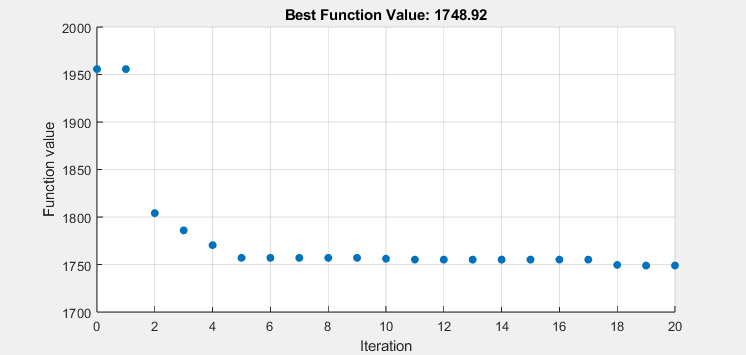

% Set nondefault solver options
options = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    20,"MaxStallIterations",10,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options